%% Simulation of linear system of monocopter with flaps 
% clc
% clear all
% close all
 
% load ka_flap.mat
% load ka_flap_NDI.mat

%% Parameters
J = 3.2284E-6; % moment of inertia of the rotor 3.2284E-6
b = 3.5077E-6; % motor viscous friction constant 3.5077E-6
K = 0.0274; % electromotive force constant, motor torque constant 0.0274 
R = 4; % electric resistance 
L = 2.75E-6; % electric inductance  
%Jxx = 100; % symmetrical so most of it is abt x so therefore Jxx = 0.0005713669 if tracking was ideal
Jxx_1st = 110; 
Jxx_2nd = 130; 
Jzz = 0.0005982825;
plot_variable = 1;
pitch = 25.61; % deg
pitch = abs(pitch);
% (bod pitch * ka * motor rpm) contributes to lift force for disk torque due to total pitch generated
ka = 3.0E-4; % based on sam values wud be 5.413E-3, but this probably 8.9574E-6
ka = ka*plot_variable; % x1, x2, x3, x4, x5...all the way to x13, default is x 10
rps = -40.9663;
rps_squared = rps^2;
cl = 0.5; % naca 0006, includes flap and wing est of 0.5
cd = 0.052; % naca 0006
g = 9.81;
rho = 1.225;
radius = 0.26;
chord_length = 0.12;
mass = 0.053; % added servo and rods 0.053
altitude = 1.25;
coam = -1; % conservation of angular momentum so reversed
Jxx = 1/4*mass*(radius)^2;



% for x:
% 1.5 - 0.5
% 1.25 - 0.5
% 1.0 - 0.5

% for y:
% 2.0 -  0.85
% 1.75 - 0.9 
% 1.5 - 0.95
% 1.25 - 1.05
% 1.0 - 1.2

torque_w_mass = radius*((cl*pitch*ka*rps_squared*rho*chord_length*(radius^3))/(6));
drag_rotation = (cd*pitch*ka*rps_squared*rho*chord_length*(radius^3))/(6*mass);
moving_axis = 'x';


if moving_axis == 'x'
    com = 1/((g + drag_rotation)); % omega abt y is positive (roll) linear acc x
elseif moving_axis == 'y'
    com = 1/(-(g + drag_rotation)); % omega abt x is negative (pitch) linear acc y
end


linesize = 3;
Fontsize = 10;
scaling = 1;

t = 0:0.01:5;
% monocopter precession is like a speed booster lol
% linear acceleration function below
if moving_axis == 'x'   
    u3 = scaling*(1/3*(sin((2.2*t)-(pi/2)))); % omega abt y, linear acc x
    u = scaling*(sin((2.2*t)-(pi/2))); % omega abt y, linear acc x  
elseif moving_axis == 'y'   
    u3 = scaling*(1/3*sin((2.5*t)-(pi))); % omega abt x, linear acc y
    u = scaling*(sin((2.5*t)-(pi))); % omega abt x, linear acc y
end


%% servo and angular acceleration feedback
%omega_dot = torque_w_mass/Jxx;
omega_dot = torque_w_mass;
omega_dot_1st = torque_w_mass;
omega_dot_2nd = torque_w_mass;

s = tf('s');
servo = K/(s*((J*s+b)*(L*s+R)+K^2)); % includes the integral to positional angle alrd
% H_servo = 3.54; % w feedback
H_servo = 0.0; % wo feedback (currently in place for the flaps ver wj is building)
H_omega_dot_tf = 1; % feedback activated  
stf = servo/(1+(servo*H_servo));
% stf = feedback(servo,1);
% isstable(stf)
% pole(stf)
%omega_dot_tf = stf; % ndi

response_delay = 0.02; % Monocopter tpp angular acceleration delay
%omega_dot = (1/omega_dot)*stf*omega_dot*response_delay;
omega_dot = stf*omega_dot;
omega_dot_1st = stf*omega_dot_1st;
omega_dot_2nd = stf*omega_dot_2nd;

% isstable(omega_dot_tf)
% pole(omega_dot_tf)

[omega_dot_controller,info] = pidtune(omega_dot,'P')

omega_dot_controller =
 
  Kp = 1.53e+03
 
P-only controller.
Model Properties


info = struct with fields:
                Stable: 1
    CrossoverFrequency: 34.1919
           PhaseMargin: 60.0002


omega_dot_tf_c = feedback(omega_dot_controller*omega_dot,1);
omega_dot_tf = feedback(omega_dot,1);

%omega_dot_tf_1st = feedback(omega_dot_controller*omega_dot_1st,1);
%omega_dot_tf_2nd = feedback(omega_dot_controller*omega_dot_2nd,1);

omega_dot_tf_1st = feedback(omega_dot_1st,1);
omega_dot_tf_2nd = feedback(omega_dot_2nd,1);

% omega_dot_tf = feedback(omega_dot,1); % implement feedback for tf which is servo to become servo/(1+(servo*H)
% isstable(omega_dot_tf)
% pole(omega_dot_tf)

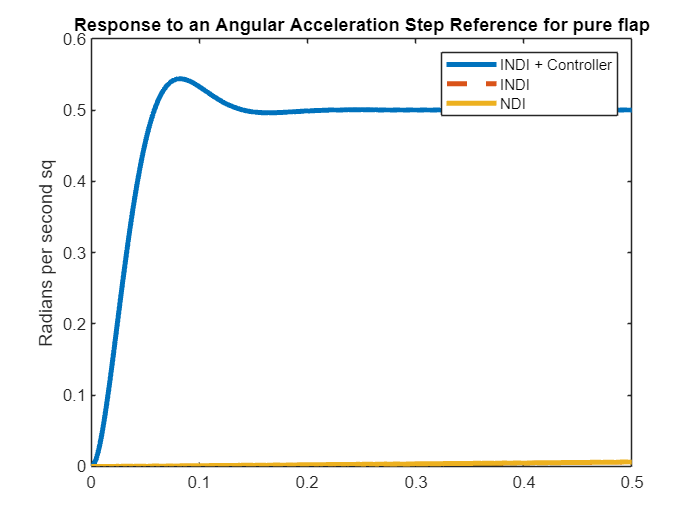

% to simulate step input of a single servo angle
st = 0:0.001:0.50;
% Config = RespConfig('Amplitude',3.5+0.04);
% step(stf, st, Config) % step function here is in the form of a servo angle 
% ylabel('Position, \theta (radians)')
% title('Response to a Step Reference (servo)')

%% for omega_dot_tf
Config = RespConfig('Amplitude',0.5); 
step_pure_flap_c = step(omega_dot_tf_c, st, Config);
step_pure_flap_nc = step(omega_dot_tf, st, Config);
step_pure_flap_ndi = step(omega_dot, st, Config);
plot(st,step_pure_flap_c,'LineWidth',linesize)
hold on
plot(st,step_pure_flap_nc,'lineStyle','--','LineWidth',linesize)
plot(st,step_pure_flap_ndi,'LineWidth',linesize)
hold off
ylabel('Radians per second sq')
title('Response to an Angular Acceleration Step Reference for pure flap')
legend('INDI + Controller','INDI','NDI')

%% to simulate disturbance step input

% [omega_dot_pi,info_d] = pidtune(stf*torque_w_mass,'PID')
% disturbance_torque_tf = 1/(Jxx+(omega_dot_controller*H_omega_dot_tf*Jxx*stf)); % w feedback

disturbance_torque_tf_c = 1/(Jxx*(1+(omega_dot_controller*H_omega_dot_tf*stf*torque_w_mass)));
disturbance_torque_tf_nc = 1/(Jxx*(1+(H_omega_dot_tf*stf*torque_w_mass)));
disturbance_torque_tf_ndi = 1/(Jxx*(1+(0*stf*torque_w_mass)));

%disturbance_torque_tf = ((s^2)*com)/(((s^2)*com)+(H_omega_dot_tf*omega_dot)) % w feedback
% disturbance_torque_tf = 1/Jxx % wo feedback
dt = st;
isstable(disturbance_torque_tf_c)

ans = logical
   1


pole(disturbance_torque_tf_c)

ans = 1.0e+06 *

  -1.4545 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i


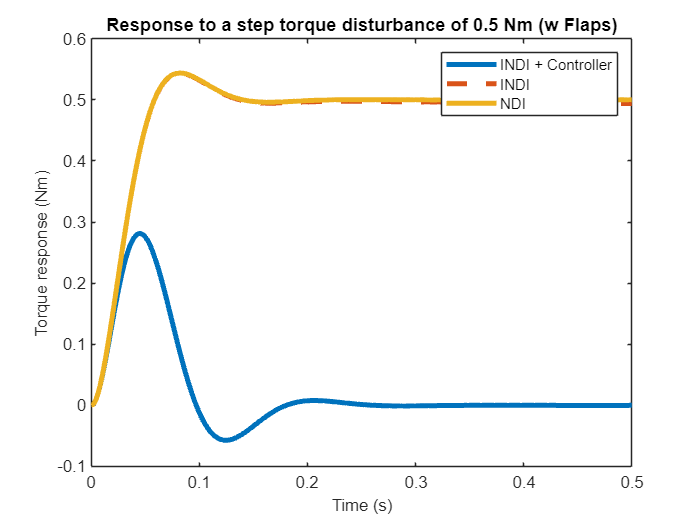


% Config = RespConfig('Amplitude',0.5,'Delay',0.05);
% disturbance_acc_c = step(disturbance_torque_tf_c, dt, Config); % step function here is in the form of a servo angle 
% disturbance_acc_nc = step(disturbance_torque_tf_nc, dt, Config);
% disturbance_acc_ndi = step(disturbance_torque_tf_ndi, dt, Config);

disturbance_input_torque = step_pure_flap_c;
disturbance_acc_c = lsim(disturbance_torque_tf_c,disturbance_input_torque,dt); 
disturbance_acc_nc = lsim(disturbance_torque_tf_nc,disturbance_input_torque,dt); 
disturbance_acc_ndi = lsim(disturbance_torque_tf_ndi,disturbance_input_torque,dt); 

disturbance_pure_flap_torque_c = disturbance_acc_c*Jxx;
disturbance_pure_flap_torque_nc = disturbance_acc_nc*Jxx;
disturbance_pure_flap_torque_ndi = disturbance_acc_ndi*Jxx;

plot(dt,disturbance_pure_flap_torque_c,'LineWidth',linesize)
hold on
plot(dt,disturbance_pure_flap_torque_nc,'lineStyle','--','LineWidth',linesize)
plot(dt,disturbance_pure_flap_torque_ndi,'LineWidth',linesize)
hold off
ylim([-0.1 0.6])
% ylabel('$\frac{acceleration output}{acceleration due to disturbance}$','Interpreter','latex','FontSize',Fontsize)
ylabel('Torque response (Nm)','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Response to a step torque disturbance of 0.5 Nm (w Flaps)')
legend('INDI + Controller','INDI','NDI')

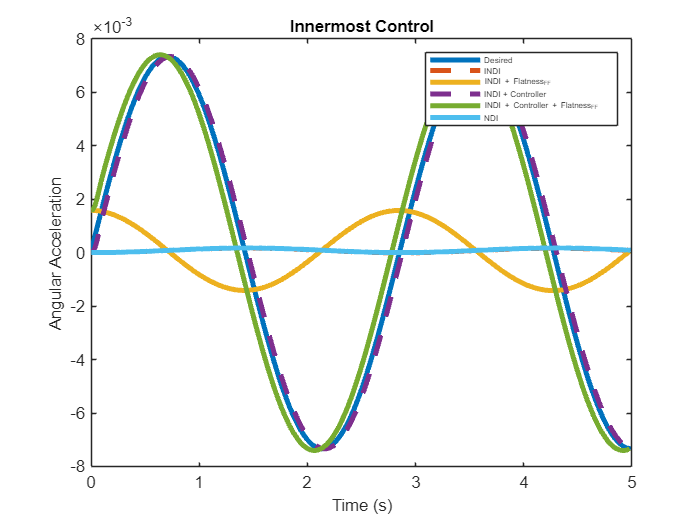

% inner raterate control loop (INDI) snap

% isstable(omega_dot_tf)
% pole(omega_dot)
u3_dot = transpose(diff(u3)); % ref bod rate - 0 fb = ref bod raterate
u3_dotdot = diff(u3_dot);


flatness_component_snap = u3_dotdot/com;  % ff bod raterate 


indi = lsim(omega_dot_tf,u3_dot,t(1,1:500)); % INDI
indi_c = lsim(omega_dot_tf_c,u3_dot,t(1,1:500)); % INDI w controller
%indi_1st = lsim(omega_dot_tf_1st,u3_dot,t(1,1:500)); % INDI
%indi_2nd = lsim(omega_dot_tf_2nd,u3_dot,t(1,1:500)); % INDI
ndi = lsim(omega_dot,u3_dot,t(1,1:500)); % NDI very big

plot (t(1,1:500),u3_dot,'LineWidth',linesize)
hold on
plot(t(1,1:500),indi,'lineStyle','--','LineWidth',linesize)
plot(t(1,1:499),indi(1:499,:)+flatness_component_snap,'LineWidth',linesize)
plot(t(1,1:500),indi_c,'lineStyle','--','LineWidth',linesize)
plot(t(1,1:499),indi_c(1:499,:)+flatness_component_snap,'LineWidth',linesize)
%plot(t,indi_1st,'LineWidth',linesize)
%plot(t,indi_2nd,'lineStyle','--','LineWidth',linesize)
plot(t(1,1:500),ndi,'LineWidth',linesize) % NDI can be tested
hold off
xlim([0.0 5])

ylabel('Angular Acceleration','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Innermost Control','FontSize',Fontsize)
legend('Desired','INDI','INDI + Flatness_FF','INDI + Controller','INDI + Controller + Flatness_FF','NDI','FontSize',5)

%legend('Desired','INDI','INDI + Flatness_FF','NDI','FontSize',Fontsize)
%legend('Desired','INDI','INDI_1st','INDI_2nd','NDI','FontSize',Fontsize)

% Error_indi = u3_dot - indi;
% Error_indi_flatness = u3_dot(1:499,:) - (indi(1:499,:)+flatness_component_snap);
% Error_indi_c = u3_dot - indi_c;
% Error_indi_flatness_c = u3_dot(1:499,:) - (indi_c(1:499,:)+flatness_component_snap);
% 
% Error_indi = (Error_indi.^2);
% Error_indi_flatness = (Error_indi_flatness.^2);
% Error_indi_c = (Error_indi_c.^2);
% Error_indi_flatness_c = (Error_indi_flatness_c.^2);
% 
% rmse_indi = sqrt(sum(Error_indi)/500);
% rmse_indi_flatness = sqrt(sum(Error_indi_flatness)/499);
% rmse_indi_c = sqrt(sum(Error_indi_c)/500);
% rmse_indi_flatness_c = sqrt(sum(Error_indi_flatness_c)/499);

% inner rate control loop (INDI) jerk

%omega = (s+D)*com*omega_dot_tf*(1/(s^2))*1/com; % jerk only
u3_dot = u3_dot/com; 
u3 = transpose(u3);
u3 = u3/com; %ref bod angle - 0 fb = ref bod rate
flatness_component_jerk = u3_dot;  % ff bod rate

omega_tf_nc = omega_dot_tf*(1/(s)); % no controller
[omega_controller_nc,omega_info_nc] = pidtune(omega_tf_nc,'PD');
omega_tf_nc = feedback(omega_controller_nc*omega_tf_nc,1); % jerk and snap INDI

omega_tf_ndi = omega_dot*(1/(s)); % jerk and snap NDI no loop
%[omega_controller_ndi,omega_info_ndi] = pidtune(omega_tf_ndi,'PD');
%omega_tf_ndi = feedback(omega_controller_ndi*omega_tf_ndi,1);

omega = omega_dot_tf_c*(1/(s)); % w controller
[omega_controller,omega_info] = pidtune(omega,'PD')

omega_controller =
 
             
  Kp + Kd * s
             

  with Kp = 31.3, Kd = 0.799
 
Continuous-time PD controller in parallel form.
Model Properties


omega_info = struct with fields:
                Stable: 1
    CrossoverFrequency: 42.0216
           PhaseMargin: 60.0000


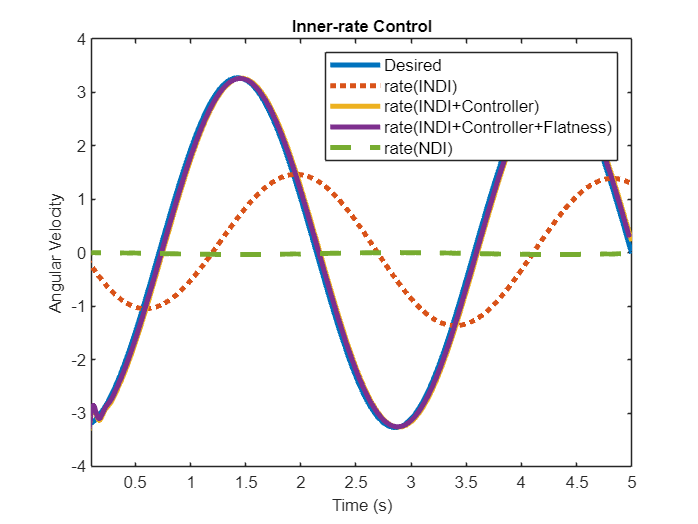

omega_tf_c = feedback(omega_controller*omega,1); % jerk and snap INDI
omega_tf = feedback(omega,1); % jerk and snap INDI
% isstable(omega_tf)
% pole(omega_tf)

rate_indi = lsim(omega_tf,u3,t); % w tpp tracking
rate_indi_c = lsim(omega_tf_c,u3,t); % w tpp tracking
rate_ndi = lsim(omega_tf_ndi,u3,t); % wo tpp tracking
plot (t,u3,'LineWidth',linesize)
hold on
plot(t,rate_indi,'lineStyle',':','LineWidth',linesize)
plot(t,rate_indi_c,'LineWidth',linesize)
plot(t(1,1:499),rate_indi_c(1:499,:)+flatness_component_jerk(1:499,:)+flatness_component_snap,'LineWidth',linesize)
%plot(t(1,1:499),rate_indi(1:499,:)+flatness_component_snap(1:499,:),'LineWidth',linesize)
plot(t,rate_ndi,'lineStyle','--','LineWidth',linesize)
%plot(t,jerk+snap+gyro_y_flap,'LineWidth',linesize) % linear acc y
%plot(t,jerk+snap+gyro_x_flap,'LineWidth',linesize) % linear acc x
hold off
xlim([0.1 5])

ylabel('Angular Velocity','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Inner-rate Control','FontSize',Fontsize)
legend('Desired','rate(INDI)','rate(INDI+Controller)','rate(INDI+Controller+Flatness)','rate(NDI)','FontSize',Fontsize)

%legend('Desired','rate(INDI)','rate(NDI)','FontSize',Fontsize)


% outer angle control loop (INDI)
angle = omega_tf_c*(1/(s));
[angle_controller,angle_info] = pidtune(angle,'PD')

angle_controller =
 
             
  Kp + Kd * s
             

  with Kp = 28.2, Kd = 0.116
 
Continuous-time PD controller in parallel form.
Model Properties


angle_info = struct with fields:
                Stable: 1
    CrossoverFrequency: 25.4497
           PhaseMargin: 60.0000


angle_tf_c = feedback(angle_controller*angle,1);

% no innermost loop ctrl
angle_nc = omega_tf_nc*(1/(s));
[angle_controller_nc,angle_info_nc] = pidtune(angle_nc,'PD')

angle_controller_nc =
 
             
  Kp + Kd * s
             

  with Kp = 0.0984, Kd = 1.75
 
Continuous-time PD controller in parallel form.
Model Properties


angle_info_nc = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.0919
           PhaseMargin: 60.0000


angle_tf_nc = feedback(angle_controller_nc*angle_nc,1);

angle_tf_ndi = omega_tf_ndi*(1/(s)); % wo close loop for bod rates and raterate
[angle_controller_ndi,angle_info_ndi] = pidtune(angle_tf_ndi,'P')

angle_controller_ndi =
 
  Kp = 9.06e+07
 
P-only controller.
Model Properties


angle_info_ndi = struct with fields:
                Stable: 0
    CrossoverFrequency: 104.8521
           PhaseMargin: NaN


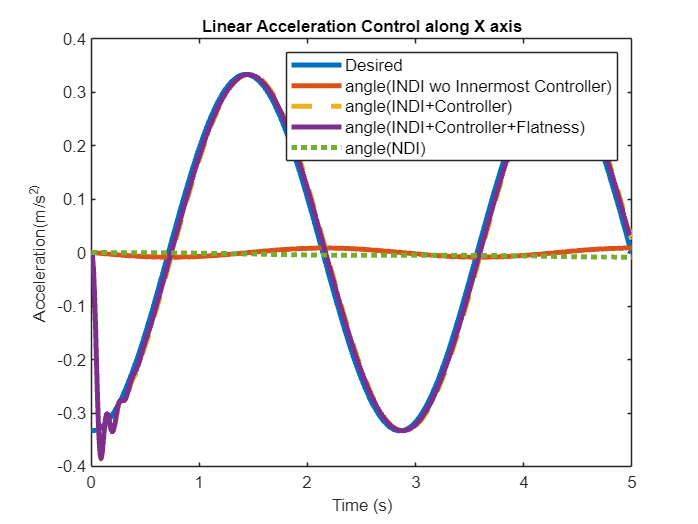

angle_tf_ndi = feedback(angle_tf_ndi,1);
%[angle_controller_ndi,angle_ndi_info] = pidtune(angle_ndi,'PID');
%angle_tf_ndi = feedback(angle_controller_ndi*angle_ndi,1);


% isstable(angle_tf)
% pole(angle_tf)

angle_indi_c = lsim(angle_tf_c,u3,t);
angle_indi = lsim(angle_tf_nc,u3,t);
angle_ndi = lsim(angle_tf_ndi,u3,t);
plot (t,u3*com,'LineWidth',linesize)
hold on
plot(t,angle_indi*com,'LineWidth',linesize)
plot(t,angle_indi_c*com,'lineStyle','--','LineWidth',linesize)
plot(t(1,1:499),(angle_indi_c(1:499,:)+flatness_component_jerk(1:499,:)+flatness_component_snap)*com,'LineWidth',linesize)
plot(t,angle_ndi*com,'lineStyle',':','LineWidth',linesize)
hold off
%ylim([-0.4 0.4])

ylabel('Acceleration(m/s^2)','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
if moving_axis == 'x'  
    title('Linear Acceleration Control along X axis','FontSize',Fontsize)
elseif moving_axis == 'y'
    title('Linear Acceleration Control along Y axis','FontSize',Fontsize)
end
legend('Desired','angle(INDI wo Innermost Controller)','angle(INDI+Controller)','angle(INDI+Controller+Flatness)','angle(NDI)','FontSize',Fontsize)


Error_indi_nc = (u3 - angle_indi)*com;
Error_indi_c = (u3 - angle_indi_c)*com;
Error_indi_c_flatness = com*(u3(1:499,:) - (angle_indi_c(1:499,:)+flatness_component_jerk(1:499,:)+flatness_component_snap));
Error_ndi = (u3 - angle_ndi)*com;

Error_indi_nc = (Error_indi_nc.^2);
Error_indi_c = (Error_indi_c.^2);
Error_indi_c_flatness = (Error_indi_c_flatness.^2);
Error_ndi = (Error_ndi.^2);

rmse_indi_nc = sqrt(sum(Error_indi_nc)/501)

rmse_indi_nc = 0.2355

rmse_indi_c = sqrt(sum(Error_indi_c)/501)

rmse_indi_c = 0.0348

rmse_indi_c_flatness = sqrt(sum(Error_indi_c_flatness)/499)

rmse_indi_c_flatness = 0.0325

rmse_ndi = sqrt(sum(Error_ndi)/501)

rmse_ndi = 0.2369